close all; clear all; clc

## Travelling wave benchmark

The equation of a plane, harmonic (sinusoildal) wave propagating in x-direction and damped by the material damping of the soil is given by:


$$u(x,t) = u_0 e^{i(\omega t - kx)}\cdot e^{-\alpha x}$$


where:

circular frequency:


$$\omega= 2 \pi f $$


wave number [rad/m]:

 
$$k = \omega/V$$


wave velocity:

 
$$V = f L$$


coefficient of attenuation [1/m]:


$$\alpha = \frac{\psi f}{2 V}$$


with $u_0 \rightarrow 
$amplitude [m], $V \rightarrow$wave velocity [m/s] , $\omega \rightarrow$ circular frquency [rad/sec], $L \rightarrow$wave length [m],  $f \rightarrow$ frequency [Hz], $\psi\rightarrow$specific damping capacity [-]

### Wave velocity

Geophones are normally used to monitor the vibrations transmitted to the surroundings during vibrodriving. Geophones measure the vertical soil velocity. 

Differentiate the traveling wave equation we get:


$$v(x,t) = u_0 i \omega e^{i(\omega t - kx)}\cdot e^{-\alpha x}$$


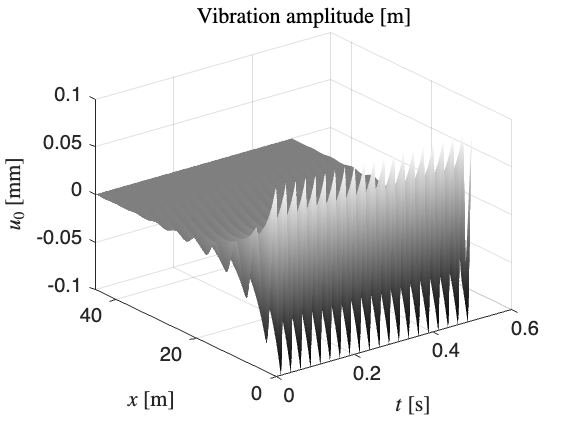

dt = 0.001;

t = 0:dt:5;

t_plot = .5;

x = 0:0.1:45;

freq = 40; %Hz

L = 5;%5; % wave length

V = freq*L;% wave velocity

omega = 2*pi*freq; % circular freq

u0 = 0.0001; % amplitude

psi = 1.5;

alpha = (psi*freq)/(2*V);

dt = t(2)-t(1);

U_damped = zeros(length(x),length(t));
V_damped = zeros(length(x),length(t));

k = omega/V;

for j=1:length(t)
    U_damped(:,j) = u0*exp(1i*(omega*t(j)-x*k)).*exp(-alpha*x); 
    V_damped(:,j) = u0*1i*omega*exp(1i*(omega*t(j)-x*k)).*exp(-alpha*x); 
end

figure;
% we only plot a bit of the data that we generated so we can see the waves
% better
indx_plot = find(t==t_plot); 
[X_mesh,Y_mesh] = meshgrid(t(1:indx_plot),x);
surf(X_mesh,Y_mesh,real(U_damped(:,1:indx_plot))*1000);
shading interp; 
xlabel('$t$ [s]','Interpreter','latex'); 
ylabel('$x$ [m]','Interpreter','latex'); 
zlabel('$u_0$ [mm]','Interpreter','latex')
colormap("gray")
title('Vibration amplitude [m]','Interpreter','latex')

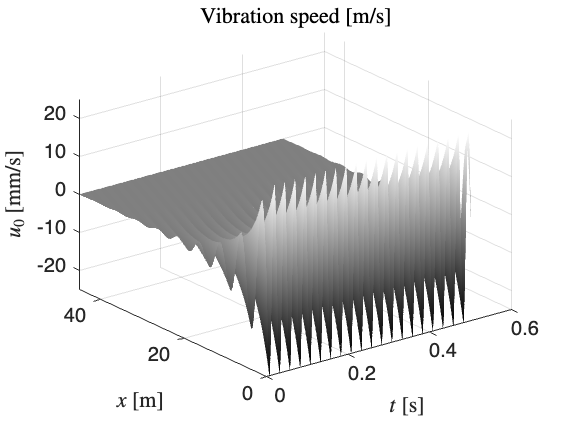

figure;

indx_plot = find(t==t_plot);
[X_mesh,Y_mesh] = meshgrid(t(1:indx_plot),x);
surf(X_mesh,Y_mesh,real(V_damped(:,1:indx_plot))*1000);
shading interp; 
xlabel('$t$ [s]','Interpreter','latex'); 
ylabel('$x$ [m]','Interpreter','latex'); 
zlabel('$u_0$ [mm/s]','Interpreter','latex')
colormap("gray")
title('Vibration speed [m/s]','Interpreter','latex')

### Introduction of noise

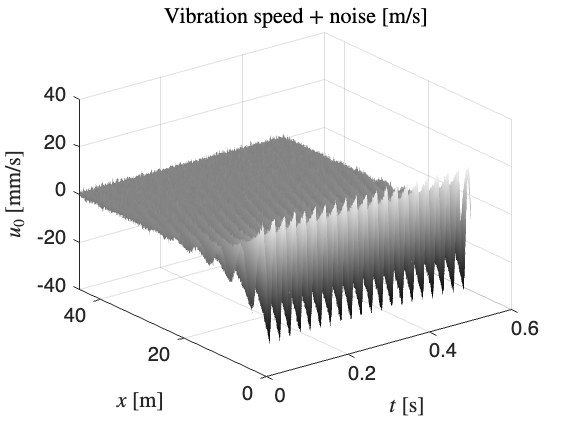

noise_lev = 1e-3;

V_noisy = V_damped + noise_lev*randn(size(V_damped));

surf(X_mesh,Y_mesh,real(V_noisy(:,1:indx_plot))*1000);
shading interp; 
xlabel('$t$ [s]','Interpreter','latex'); 
ylabel('$x$ [m]','Interpreter','latex'); 
zlabel('$u_0$ [mm/s]','Interpreter','latex')
colormap("gray")
title('Vibration speed + noise [m/s]','Interpreter','latex')

### Sampling of original signal

We simulate geophones located at different radial locations. The measurent system we want to simulate has a high sampling rate but only a few spatially distributed measurement point. 

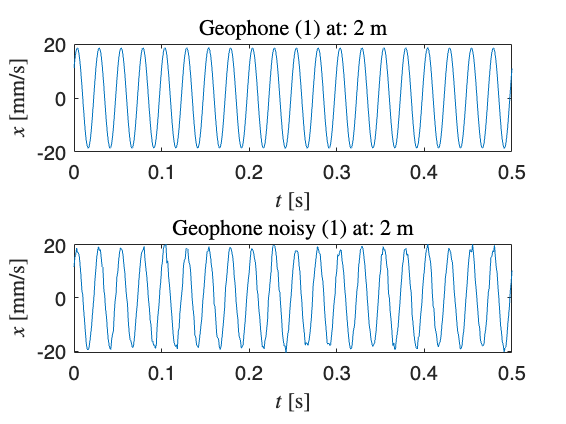

Data_V = real(V_damped);
Data_V_noisy = real(V_noisy);

meas_points = [2 5 10 20 40]; %[m]

idx_meas_points = zeros(1, length(meas_points));

t_plot_geo = 0.5;

for i = 1:length(meas_points)
    [~, idx_meas_points(i)] = min(abs(x - meas_points(i)));
end

sim_geophones = Data_V(idx_meas_points,:);
sim_geophones_noisy = Data_V_noisy(idx_meas_points,:);

indx_plot_geo = find(t==t_plot_geo);

figure;
subplot(2,1,1)
plot(t(1:indx_plot_geo),sim_geophones(1,1:indx_plot_geo)*1000)
xlabel('$t$ [s]','Interpreter','latex'); 
ylabel('$x$ [mm/s]','Interpreter','latex'); 
title("Geophone (1) at: "+int2str(meas_points(1))+" m",'Interpreter','latex')
% ylim([-30 30])

subplot(2,1,2)
plot(t(1:indx_plot_geo),sim_geophones_noisy(1,1:indx_plot_geo)*1000)
xlabel('$t$ [s]','Interpreter','latex'); 
ylabel('$x$ [mm/s]','Interpreter','latex'); 
title("Geophone noisy (1) at: "+int2str(meas_points(1))+" m",'Interpreter','latex')

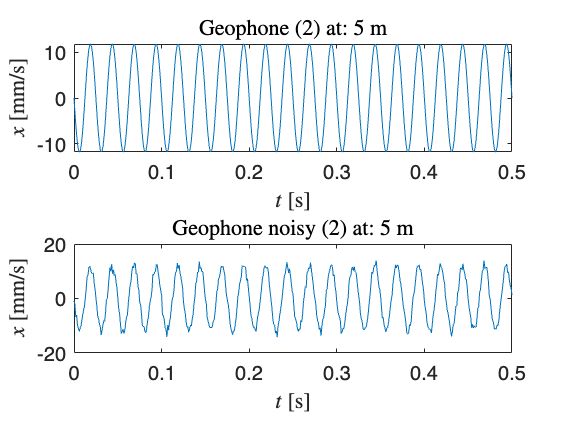

% ylim([-30 30])

figure;
subplot(2,1,1)
plot(t(1:indx_plot_geo),sim_geophones(2,1:indx_plot_geo)*1000)
xlabel('$t$ [s]','Interpreter','latex'); 
ylabel('$x$ [mm/s]','Interpreter','latex'); 
title("Geophone (2) at: "+int2str(meas_points(2))+" m",'Interpreter','latex')
% ylim([-30 30])

subplot(2,1,2)
plot(t(1:indx_plot_geo),sim_geophones_noisy(2,1:indx_plot_geo)*1000)
xlabel('$t$ [s]','Interpreter','latex'); 
ylabel('$x$ [mm/s]','Interpreter','latex'); 
title("Geophone noisy (2) at: "+int2str(meas_points(2))+" m",'Interpreter','latex')

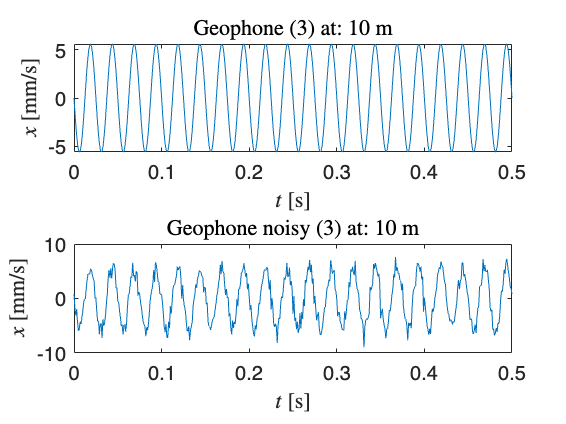

% ylim([-30 30])

figure;
subplot(2,1,1)
plot(t(1:indx_plot_geo),sim_geophones(3,1:indx_plot_geo)*1000)
xlabel('$t$ [s]','Interpreter','latex'); 
ylabel('$x$ [mm/s]','Interpreter','latex'); 
title("Geophone (3) at: "+int2str(meas_points(3))+" m",'Interpreter','latex')
% ylim([-30 30])

subplot(2,1,2)
plot(t(1:indx_plot_geo),sim_geophones_noisy(3,1:indx_plot_geo)*1000)
xlabel('$t$ [s]','Interpreter','latex'); 
ylabel('$x$ [mm/s]','Interpreter','latex'); 
title("Geophone noisy (3) at: "+int2str(meas_points(3))+" m",'Interpreter','latex')

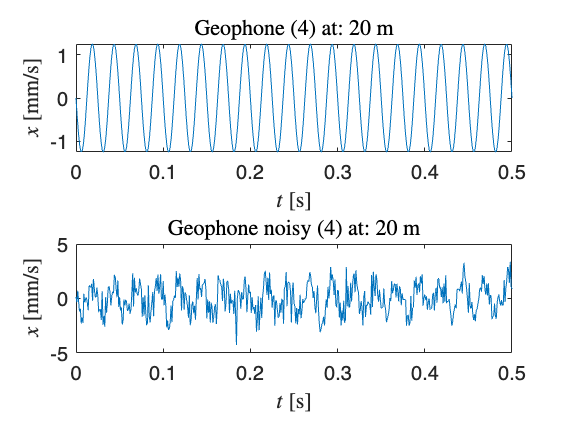


figure;
subplot(2,1,1)
plot(t(1:indx_plot_geo),sim_geophones(4,1:indx_plot_geo)*1000)
xlabel('$t$ [s]','Interpreter','latex'); 
ylabel('$x$ [mm/s]','Interpreter','latex'); 
title("Geophone (4) at: "+int2str(meas_points(4))+" m",'Interpreter','latex')
% ylim([-30 30])

subplot(2,1,2)
plot(t(1:indx_plot_geo),sim_geophones_noisy(4,1:indx_plot_geo)*1000)
xlabel('$t$ [s]','Interpreter','latex'); 
ylabel('$x$ [mm/s]','Interpreter','latex'); 
title("Geophone noisy (4) at: "+int2str(meas_points(4))+" m",'Interpreter','latex')

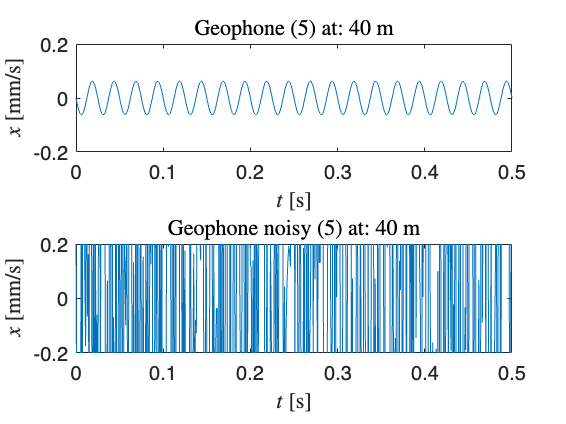


figure;
subplot(2,1,1)
plot(t(1:indx_plot_geo),sim_geophones(5,1:indx_plot_geo)*1000)
xlabel('$t$ [s]','Interpreter','latex'); 
ylabel('$x$ [mm/s]','Interpreter','latex'); 
title("Geophone (5) at: "+int2str(meas_points(5))+" m",'Interpreter','latex')
ylim([-0.2 0.2])

subplot(2,1,2)
plot(t(1:indx_plot_geo),sim_geophones_noisy(5,1:indx_plot_geo)*1000)
xlabel('$t$ [s]','Interpreter','latex'); 
ylabel('$x$ [mm/s]','Interpreter','latex'); 
title("Geophone noisy (5) at: "+int2str(meas_points(5))+" m",'Interpreter','latex')
ylim([-0.2 0.2])

## Augmented Dynamic Mode Decomposition

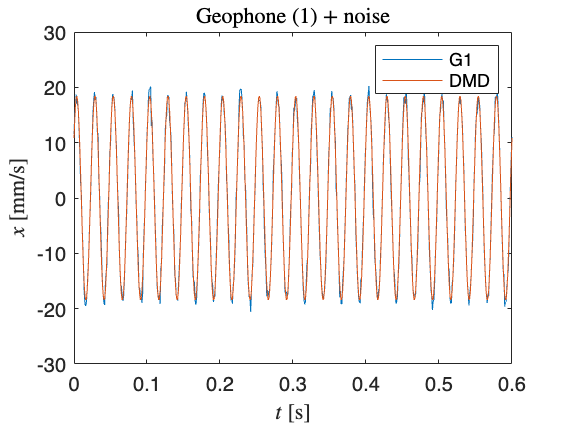

% Rank truncation
r = 8;

% Number of used geophones*
num_geo = length(meas_points);
% *if we want more geophone we also need to modify the way we calcualte
% f_aug

f = sim_geophones_noisy;
% f = sim_geophones;

% Number of delay coordinates
s = 100;

% Time to plot
t_plot_dmd = .6; % [s]
% t_plot_dmd = max(t);


l = ceil((length(f))/2);

f_aug = zeros(s*num_geo,l);


for i = 1:s
    f_aug([i s+i 2*s+i 3*s+i 4*s+i],:) = [f(1,i:l+i-1) ;f(2,i:l+i-1) ;...
        f(3,i:l+i-1) ;f(4,i:l+i-1) ;f(5,i:l+i-1)];
end

X1 = f_aug(:,1:end-1); X2 = f_aug(:,2:end);

% Perform Singular Value Decomposition (SVD) on X1
[U, S, V] = svd(X1, "econ");

% Truncate the SVD to the desired rank 'r'
Ur = U(:, 1:r);
Sr = S(1:r, 1:r);
Vr = V(:, 1:r);

% Build the low-rank approximation of the state transition matrix Atilde
Atilde = Ur' * X2 * Vr *Sr^(-1);

% Compute the eigenvalues (D) and eigenvectors (W) of Atilde
[W, D] = eig(Atilde);

% Calculate the DMD modes (Phi) using X2, Vr, Sr, and W
Phi_aug = X2 * Vr / Sr * W;

% Calculate the continuous-time frequencies (omega) from the eigenvalues
lambda = diag(D);
omega_aug = log(lambda) / dt;

% Determine the initial condition (b) in DMD space
b_aug = Phi_aug \ X1(:, 1);

% DMD prediction
f_dmd = real(Phi_aug*(b_aug.*exp(omega_aug*t)));


indx_plot_dmd = find(t==t_plot_dmd);

figure;
plot(t(1:indx_plot_dmd),f(1,1:indx_plot_dmd)*1000)
hold on
plot(t(1:indx_plot_dmd),f_dmd(1,1:indx_plot_dmd)*1000)
hold off
xlabel('$t$ [s]','Interpreter','latex'); 
ylabel('$x$ [mm/s]','Interpreter','latex'); 
if isequal(f,sim_geophones)
    title("Geophone (1)",'Interpreter','latex')
elseif isequal(f,sim_geophones_noisy)
    title("Geophone (1) + noise",'Interpreter','latex')
end
legend('G1','DMD')

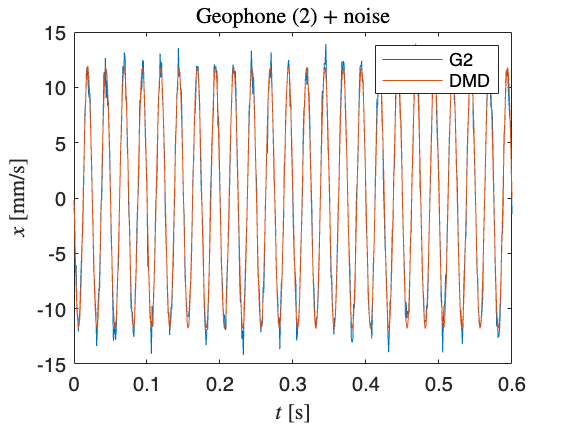


figure;
plot(t(1:indx_plot_dmd),f(2,1:indx_plot_dmd)*1000)
hold on
plot(t(1:indx_plot_dmd),f_dmd(s+1,1:indx_plot_dmd)*1000)
xlabel('$t$ [s]','Interpreter','latex'); 
ylabel('$x$ [mm/s]','Interpreter','latex'); 
if isequal(f,sim_geophones)
    title("Geophone (2)",'Interpreter','latex')
elseif isequal(f,sim_geophones_noisy)
    title("Geophone (2) + noise",'Interpreter','latex')
end
legend('G2','DMD')

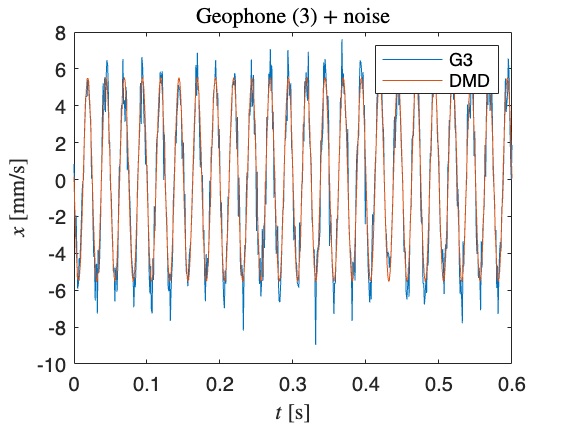


figure;
plot(t(1:indx_plot_dmd),f(3,1:indx_plot_dmd)*1000)
hold on
plot(t(1:indx_plot_dmd),f_dmd(2*s+1,1:indx_plot_dmd)*1000)
xlabel('$t$ [s]','Interpreter','latex'); 
ylabel('$x$ [mm/s]','Interpreter','latex'); 
if isequal(f,sim_geophones)
    title("Geophone (3)",'Interpreter','latex')
elseif isequal(f,sim_geophones_noisy)
    title("Geophone (3) + noise",'Interpreter','latex')
end
legend('G3','DMD')

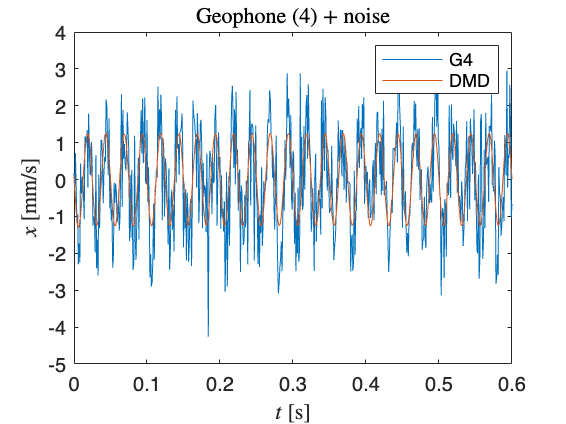


figure;
plot(t(1:indx_plot_dmd),f(4,1:indx_plot_dmd)*1000)
hold on
plot(t(1:indx_plot_dmd),f_dmd(3*s+1,1:indx_plot_dmd)*1000)
xlabel('$t$ [s]','Interpreter','latex'); 
ylabel('$x$ [mm/s]','Interpreter','latex'); 
if isequal(f,sim_geophones)
    title("Geophone (4)",'Interpreter','latex')
elseif isequal(f,sim_geophones_noisy)
    title("Geophone (4) + noise",'Interpreter','latex')
end
legend('G4','DMD')

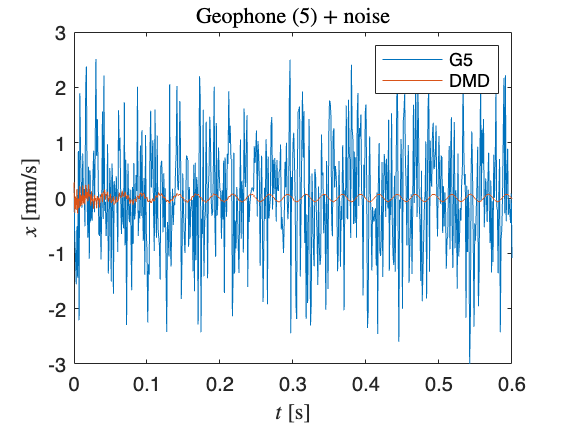


figure;
plot(t(1:indx_plot_dmd),f(5,1:indx_plot_dmd)*1000)
hold on
plot(t(1:indx_plot_dmd),f_dmd(4*s+1,1:indx_plot_dmd)*1000)
xlabel('$t$ [s]','Interpreter','latex'); 
ylabel('$x$ [mm/s]','Interpreter','latex'); 
if isequal(f,sim_geophones)
    title("Geophone (5)",'Interpreter','latex')
elseif isequal(f,sim_geophones_noisy)
    title("Geophone (5) + noise",'Interpreter','latex')
end
legend('G5','DMD')

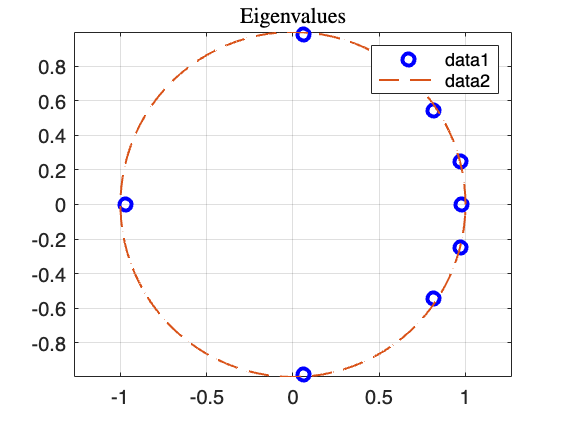



figure;

plot(real(lambda),imag(lambda),'bo','LineWidth',2)
hold on

theta = linspace(0, 2*pi, 100); % Angle values from 0 to 2*pi
x = cos(theta); % x-coordinates for the unit circle
y = sin(theta); % y-coordinates for the unit circle
% Plot the unit circle with a dashed line
plot(x, y, '--', 'LineWidth', 1); % Dashed line style and thicker line
grid on;
axis equal
title('Eigenvalues','Interpreter','latex')
legend

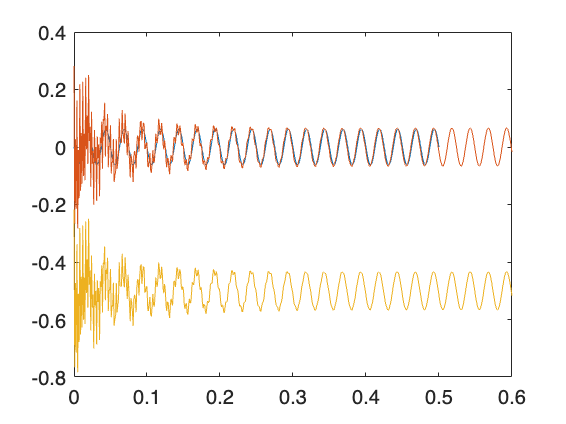

figure

plot(t(1:indx_plot_geo),sim_geophones(5,1:indx_plot_geo)*1000)
hold on
plot(t(1:indx_plot_dmd),f_dmd(4*s+1,1:indx_plot_dmd)*1000)
plot(t(1:indx_plot_dmd),f_dmd(4*s+1,1:indx_plot_dmd)*1000-0.5)

### Eigenvalue analysis

#### Eigenvalues test data

% Rank truncation
r = 5;

% Number of used geophones*
num_geo = length(meas_points);
% *if we want more geophone we also need to modify the way we calcualte
% f_aug

f = sim_geophones;

% Number of delay coordinates
s = 1;

% Time to plot
t_plot_dmd = .6; % [s]
% t_plot_dmd = max(t);


l = ceil((length(f))/2);

f_aug = zeros(s*num_geo,l);


for i = 1:s
    f_aug([i s+i 2*s+i 3*s+i 4*s+i],:) = [f(1,i:l+i-1) ;f(2,i:l+i-1) ;...
        f(3,i:l+i-1) ;f(4,i:l+i-1) ;f(5,i:l+i-1)];
end

X1 = f_aug(:,1:end-1); X2 = f_aug(:,2:end);

% Perform Singular Value Decomposition (SVD) on X1
[U, S, V] = svd(X1, "econ");

% Truncate the SVD to the desired rank 'r'
Ur = U(:, 1:r);
Sr = S(1:r, 1:r);
Vr = V(:, 1:r);

% Build the low-rank approximation of the state transition matrix Atilde
Atilde = Ur' * X2 * Vr *Sr^(-1);

% Compute the eigenvalues (D) and eigenvectors (W) of Atilde
[W, D] = eig(Atilde);

% Calculate the DMD modes (Phi) using X2, Vr, Sr, and W
Phi_aug = X2 * Vr / Sr * W;


% Calculate the continuous-time frequencies (omega) from the eigenvalues
lambda_true = diag(D);


#### Eigenvalues noisy data

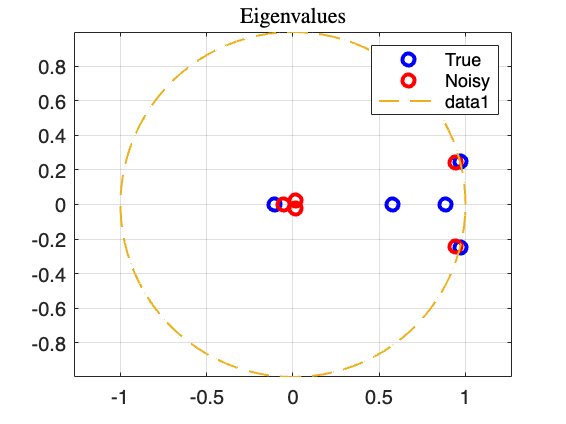

% Rank truncation
r_noisy = 5;

% Number of used geophones*
num_geo = length(meas_points);
% *if we want more geophone we also need to modify the way we calcualte
% f_aug

f_noisy = sim_geophones_noisy;

% Number of delay coordinates
s_noisy = 1;

% Time to plot
t_plot_dmd = .6; % [s]
% t_plot_dmd = max(t);


l_noisy = ceil((length(f_noisy))/2);

f_aug_noisy = zeros(s_noisy*num_geo,l_noisy);


for i = 1:s_noisy
    f_aug_noisy([i s_noisy+i 2*s_noisy+i 3*s_noisy+i 4*s_noisy+i],:) = [f_noisy(1,i:l_noisy+i-1) ;f_noisy(2,i:l_noisy+i-1) ;...
        f_noisy(3,i:l_noisy+i-1) ;f_noisy(4,i:l_noisy+i-1) ;f_noisy(5,i:l_noisy+i-1)];
end

X1_noisy = f_aug_noisy(:,1:end-1); X2_noisy = f_aug_noisy(:,2:end);

% Perform Singular Value Decomposition (SVD) on X1
[U_noisy, S_noisy, V_noisy] = svd(X1_noisy, "econ");

% Truncate the SVD to the desired rank 'r'
Ur_noisy = U_noisy(:, 1:r_noisy);
Sr_noisy = S_noisy(1:r_noisy, 1:r_noisy);
Vr_noisy = V_noisy(:, 1:r_noisy);

% Build the low-rank approximation of the state transition matrix Atilde
Atilde_noisy = Ur_noisy' * X2_noisy * Vr_noisy *Sr_noisy^(-1);

% Compute the eigenvalues (D) and eigenvectors (W) of Atilde
[W_noisy, D_noisy] = eig(Atilde_noisy);

% Calculate the DMD modes (Phi) using X2, Vr, Sr, and W
Phi_aug_noisy = X2_noisy * Vr_noisy / Sr_noisy * W_noisy;

% Calculate the continuous-time frequencies (omega) from the eigenvalues
lambda_noisy = diag(D_noisy);

figure;

plot(real(lambda_true),imag(lambda_true),'bo','LineWidth',2,'DisplayName','True')
hold on
plot(real(lambda_noisy),imag(lambda_noisy),'ro','LineWidth',2,'DisplayName','Noisy')

theta = linspace(0, 2*pi, 100); % Angle values from 0 to 2*pi
x = cos(theta); % x-coordinates for the unit circle
y = sin(theta); % y-coordinates for the unit circle
% Plot the unit circle with a dashed line
plot(x, y, '--', 'LineWidth', 1); % Dashed line style and thicker line
grid on;
axis equal
title('Eigenvalues','Interpreter','latex')
legend

#### Systematic analysis

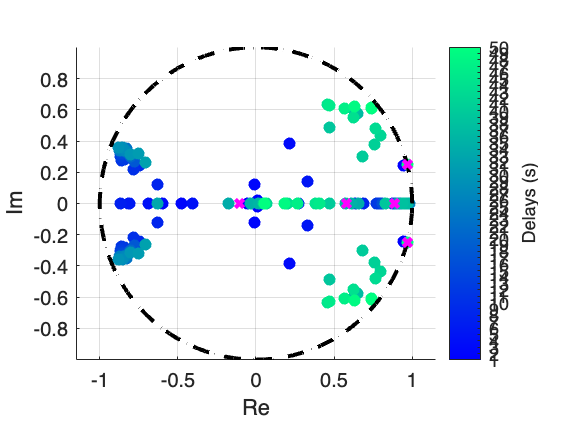

clear Omega_arr

% Rank truncation
r = 5;

% Number of used geophones*
num_geo = length(meas_points);
% *if we want more geophone we also need to modify the way we calcualte
% f_aug

f = sim_geophones_noisy;
% f = sim_geophones;


% Time to plot
% t_plot_dmd = 3; % [s]
t_plot_dmd = max(t);


l = ceil((length(f))/2);



idx_array = 1;

s_0 = 1;
s_step = 1;
s_f = 50;

for s=s_0:s_step:s_f
    % creation of augmented matrix (to reduce computational time
    f_aug = zeros(s*num_geo,l);

    % data matrices accoring to DMD
    X1 = zeros(s*num_geo,l-1);
    X2 = zeros(s*num_geo,l-1);

    for i = 1:s
        f_aug([i s+i 2*s+i 3*s+i 4*s+i],:) = [f(1,i:l+i-1) ;f(2,i:l+i-1) ;...
            f(3,i:l+i-1) ;f(4,i:l+i-1) ;f(5,i:l+i-1)];
    end

    X1 = f_aug(:,1:end-1); 
    X2 = f_aug(:,2:end);

    % Perform Singular Value Decomposition (SVD) on X1
    [U, S, V] = svd(X1, "econ");
    % Truncate the SVD to the desired rank 'r'
    Ur = U(:, 1:r);
    Sr = S(1:r, 1:r);
    Vr = V(:, 1:r);
    % Build the low-rank approximation of the state transition matrix Atilde
    Atilde = Ur' * X2 * Vr *Sr^(-1);
    % Compute the eigenvalues (D) and eigenvectors (W) of Atilde
    [W, D] = eig(Atilde);
    % Calculate the DMD modes (Phi) using X2, Vr, Sr, and W
    Phi_aug = X2 * Vr / Sr * W;
    % Calculate the continuous-time frequencies (omega) from the eigenvalues
    lambda = diag(D);
    omega_aug = log(lambda) / dt;
    % Determine the initial condition (b) in DMD space
    b_aug = Phi_aug \ X1(:, 1);

    f_dmd_extra = Phi_aug*(b_aug.*exp(omega_aug*t));

    Omega_arr(:,:,idx_array) = lambda;

    idx_array = idx_array+1;

end

figure;

[~,~,z_arr] = size(Omega_arr);

cmap = winter(z_arr);  % Create a colormap with z_arr distinct colors

for i = 1:z_arr
    hold on
    % Use the ith color from the colormap for all points in Omega(:,i)
    scatter(real(Omega_arr(:,:,i)), imag(Omega_arr(:,:,i)), [], cmap(i,:), 'filled');
    xlabel('Re');
    ylabel('Im');
end

% Set up the color bar
colormap((winter)); 
% colormap(flipud(winter)); 
cbar = colorbar;  % Add colorbar
clim([1 z_arr]); % Set the color axis to match the range of z_arr
cbar.Ticks = linspace(1, z_arr, z_arr);  % Set the ticks to match z_arr indices
cbar.TickLabels = 1:z_arr;  % Label each tick with the corresponding z_arr index
cbar.Label.String = 'Delays (s)';  % Replace with your desired label

hold on
theta = linspace(0, 2*pi, 100); % Angle values from 0 to 2*pi
x = cos(theta); % x-coordinates for the unit circle
y = sin(theta); % y-coordinates for the unit circle
% Plot the unit circle with a dashed line
plot(x, y, '--', 'LineWidth', 2,'Color','black'); % Dashed line style and thicker line
grid on;
axis equal

plot(real(lambda_true),imag(lambda_true),'bx','LineWidth',2,'Color','magenta')

### Without rank truncation

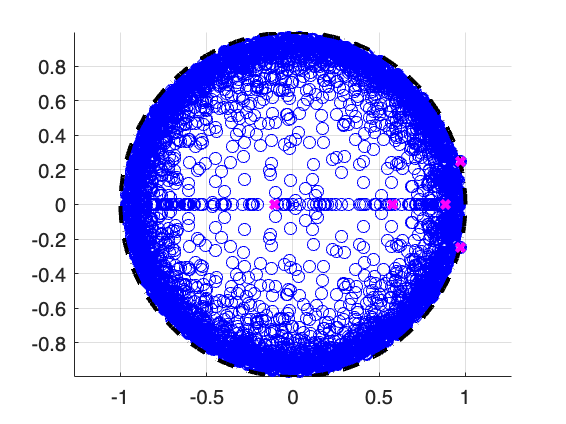

clear Omega_arr


% Number of used geophones*
num_geo = length(meas_points);
% *if we want more geophone we also need to modify the way we calcualte
% f_aug

f = sim_geophones_noisy;
% f = sim_geophones;


% Time to plot
% t_plot_dmd = 3; % [s]
t_plot_dmd = max(t);


l = ceil((length(f))/2);



q = 1;

s_0 = 1;
s_step = 1;
s_f = 50;

clear lambdaCell
for s=s_0:s_step:s_f
    % creation of augmented matrix (to reduce computational time
    f_aug = zeros(s*num_geo,l);

    % data matrices accoring to DMD
    X1 = zeros(s*num_geo,l-1);
    X2 = zeros(s*num_geo,l-1);

    for i = 1:s
        f_aug([i s+i 2*s+i 3*s+i 4*s+i],:) = [f(1,i:l+i-1) ;f(2,i:l+i-1) ;...
            f(3,i:l+i-1) ;f(4,i:l+i-1) ;f(5,i:l+i-1)];
    end

    X1 = f_aug(:,1:end-1); 
    X2 = f_aug(:,2:end);
    
    A = X2*pinv(X1);

    [W, D] = eig(A);
    % Calculate the DMD modes (Phi) using X2, Vr, Sr, and W
    % Phi_aug = X2 * Vr / Sr * W;
    Phi_aug = W;
    % Calculate the continuous-time frequencies (omega) from the eigenvalues
    lambda = diag(D);
    omega_aug = log(lambda) / dt;
    % Determine the initial condition (b) in DMD space
    b_aug = Phi_aug \ X1(:, 1);

    f_dmd_extra = Phi_aug*(b_aug.*exp(omega_aug*t));

    lambdaCell{q} = lambda;
    q = q+1;


end

figure
for i=1:length(lambdaCell)
    hold on
    plot(lambdaCell{1,i},'bo')
end
theta = linspace(0, 2*pi, 100); % Angle values from 0 to 2*pi
x = cos(theta); % x-coordinates for the unit circle
y = sin(theta); % y-coordinates for the unit circle
% Plot the unit circle with a dashed line
plot(x, y, '--', 'LineWidth', 2,'Color','black'); % Dashed line style and thicker line
grid on;
axis equal

plot(real(lambda_true),imag(lambda_true),'bx','LineWidth',2,'Color','magenta')

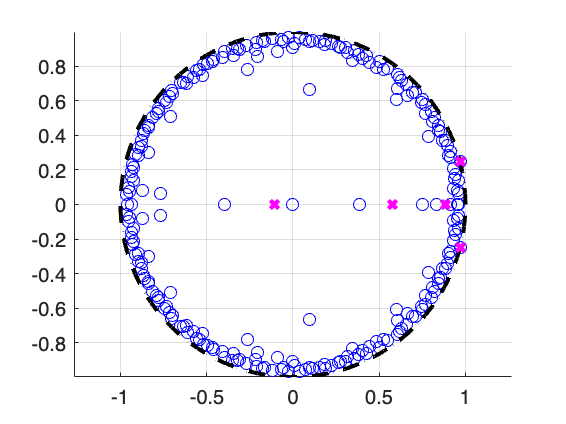

figure

hold on
plot(lambdaCell{1,50},'bo')
theta = linspace(0, 2*pi, 100); % Angle values from 0 to 2*pi
x = cos(theta); % x-coordinates for the unit circle
y = sin(theta); % y-coordinates for the unit circle
% Plot the unit circle with a dashed line
plot(x, y, '--', 'LineWidth', 2,'Color','black'); % Dashed line style and thicker line
grid on;
axis equal

plot(real(lambda_true),imag(lambda_true),'bx','LineWidth',2,'Color','magenta')
hold off